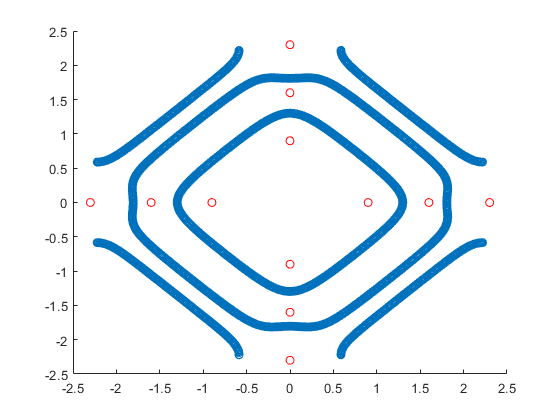

clear variables
sample = load('D:\tmp\output_change2.dat');
figure;
value = 2.3;
samplex{1} = [0.0 0.9 0.0 -0.9];
sampley{1} = [0.9 0.0 -0.9 0.0];
samplex{2} = [0.0 1.6 0.0 -1.6];
sampley{2} = [1.6 0.0 -1.6 0.0];
% samplex{3} = [0.0 2.2 0.0 -2.2];
% sampley{3} = [2.2 0.0 -2.2 0.0];
samplex{3} = [0.0 value 0.0 -value];
sampley{3} = [value 0.0 -value 0.0];
scatter(sample(:, 1), sample(:,2));
hold on;
for numIdx = 1: length(samplex)
    scatter(samplex{numIdx}, sampley{numIdx}, 'r');
end
hold off;

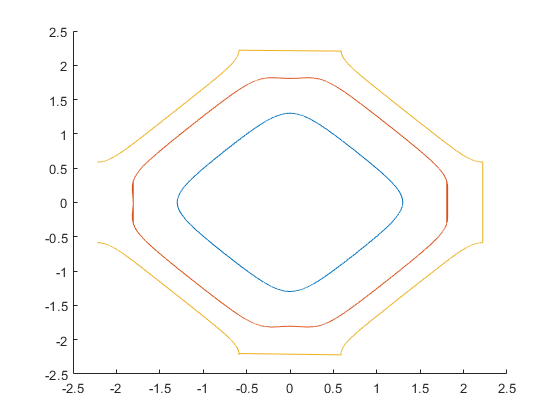

figure;
fileID = fopen("output2.dat", "w");
hold on
for numIdx = 1: 4
    if numIdx == 1
        in{numIdx} = inpolygon(sample(:, 1), sample(:, 2), samplex{numIdx}, sampley{numIdx});
    elseif numIdx == 4
        in{4} = ~in{3} & ~in{2} & ~in{1};
    else
        in{numIdx} = inpolygon(sample(:, 1), sample(:, 2), samplex{numIdx}, sampley{numIdx}) & ...
            ~in{numIdx - 1};
        i = numIdx - 1;
        while i ~= 1
            in{numIdx} = in{numIdx} & ~in{i - 1};
            i = i - 1;
        end
        
    end
    
    sampleRestricted = sample(in{numIdx}, :);
    yGreaterZero = sampleRestricted(:, 2) > 0;
    sampleGreaterZero = sampleRestricted(yGreaterZero, :);
    [levelSortedUp{numIdx}, index] = sort(sampleRestricted(yGreaterZero, 1));
    levelSortedUp{numIdx}(:, 2) = sampleGreaterZero(index, 2);
    ySmallerZero = sampleRestricted(:, 2) < 0;
    sampleSmallerZero = sampleRestricted(ySmallerZero, :);
    [levelSortedDown{numIdx}, index] = sort(sampleRestricted(ySmallerZero, 1));
    levelSortedDown{numIdx}(:, 2) = sampleSmallerZero(index, 2);
    levelSorted{numIdx} = [levelSortedUp{numIdx}; flipud(levelSortedDown{numIdx})];
    plot(levelSorted{numIdx}(:, 1), levelSorted{numIdx}(:, 2));
    for i = 1: length(levelSorted{numIdx}(:, 1))
        fprintf(fileID, "%11.7f %11.7f\n", levelSorted{numIdx}(i, 1), levelSorted{numIdx}(i, 2));
    end
    fprintf(fileID, "\n\n\n\n");
end
fclose(fileID);
hold off

% plot(levelSortedUp{1}(:, 1), levelSortedUp{1}(:, 2))